# 3.13. Последовательные и параллельные цепи

#### Последовательная цепь

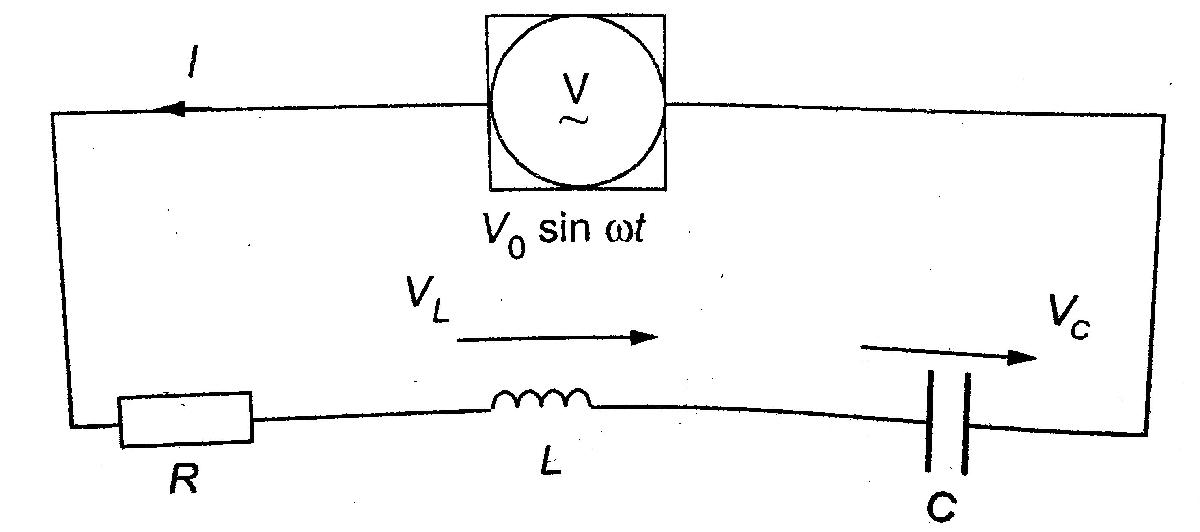

clear 
syms L I(t) C R omega V0 t
L*diff(I,t,2)+R*diff(I,t)+1/C*I==omega*V0*cos(omega*t)

$$ans(t) = R\,\frac{\partial }{\partial t}\text{I}\left(t\right)+L\,\frac{\partial^{2}}{\partial t^{2}}\text{I}\left(t\right)+\frac{\text{I}\left(t\right)}{C}=V_{0}\,\omega \,\cos\left(\omega \,t\right)$$

Стационарное решение

syms I I0 omega t phi V0
I==I0*sin(omega*t-phi)

$$ans = \text{I}=-I_{0}\,\sin\left(\varphi -\omega \,t\right)$$

I0==V0/sqrt(R^2+(omega*L-1/(omega*C))^2)

$$ans = I_{0}=\frac{V_{0}}{\sqrt{{\left(L\,\omega -\frac{1}{C\,\omega }\right)}^{2}+R^{2}}}$$

phi==atan((omega*L-1/(omega*C))/R)

$$ans = \varphi =\mathrm{atan}\left(\frac{L\,\omega -\frac{1}{C\,\omega }}{R}\right)$$

*Добротность*

syms Q0 omega0
Q0==1/R*sqrt(L/C)==omega0*L/R==1/(omega0*R*C)

$$ans = \left(\left(Q_{0}=\frac{\sqrt{\frac{L}{C}}}{R}\right)=\frac{L\,\omega_{0}}{R}\right)=\frac{1}{C\,R\,\omega_{0}}$$

*Резонансная частота*

syms f0
f0==omega0/(2*pi)==1/(sym(2)*pi)*1/sqrt(L*C)

$$ans = \left(f_{0}=\frac{\omega_{0}}{2\,\pi }\right)=\frac{1}{2\,\pi \,\sqrt{C\,L}}$$

*Импеданс*

syms Z a
Z==R+1j*(omega*L-1/(omega*C))==R*(1+1j*a)

$$ans = \left(Z=R+L\,\omega \,\mathrm{i}-\frac{\mathrm{i}}{C\,\omega }\right)=R\,\left(1+a\,\mathrm{i}\right)$$

*Нормированный импеданс*

a==Q0*(omega/omega0-omega0/omega)

$$ans = a=Q_{0}\,\left(\frac{\omega }{\omega_{0}}-\frac{\omega_{0}}{\omega }\right)$$

*Токи полумощности *$\omega_1$* и* $\omega_2$ (если $a=\pm 1$)

syms omega1 omega2
omega1/omega0==1/(2*Q0)+sqrt(1/(4*Q0^2)+1),omega2/omega0==-1/(2*Q0)+sqrt(1/(4*Q0^2)+1)

$$ans = \frac{\omega_{1}}{\omega_{0}}=\frac{1}{2\,Q_{0}}+\sqrt{\frac{1}{4\,{Q_{0}}^{2}}+1}$$

$$ans = \frac{\omega_{2}}{\omega_{0}}=\sqrt{\frac{1}{4\,{Q_{0}}^{2}}+1}-\frac{1}{2\,Q_{0}}$$

Q0==omega0/(omega1-omega2)

$$ans = Q_{0}=\frac{\omega_{0}}{\omega_{1}-\omega_{2}}$$

omega1*omega2==omega0^2

$$ans = \omega_{1}\,\omega_{2}={\omega_{0}}^{2}$$

*Ширина полосы (в Гц)*

syms B
B==(omega1-omega2)/(2*pi)==omega0/(2*pi*Q0)==1/(sym(2)*pi)*R/L

$$ans = \left(\left(B=\frac{\omega_{1}-\omega_{2}}{2\,\pi }\right)=\frac{\omega_{0}}{2\,Q_{0}\,\pi }\right)=\frac{R}{2\,L\,\pi }$$

Формулы для $\omega =\omega_0 \;,Q_0 \gg 1$

syms V_L V_C delta V
V_L==1j*Q0*V

$$ans = V_{L}=Q_{0}\,V\,\mathrm{i}$$

V_C==-1j*Q0*V

$$ans = V_{C}=-Q_{0}\,V\,\mathrm{i}$$

Z==R*(1+1j*2*delta*Q0)

$$ans = Z=R\,\left(1+2\,Q_{0}\,\delta \,\mathrm{i}\right)$$

delta==(omega-omega0)/omega0 % относительная разность частот

$$ans = \delta =\frac{\omega -\omega_{0}}{\omega_{0}}$$

#### Выключение источника питания (Колебательный контур)

*I.* $\omega_0 >\gamma$

syms omega_c gamma omega omega0 I I0 alpha
omega_c==sqrt(omega^2-gamma^2), omega0==1/sqrt(L*C)

$$ans = \omega_{c}=\sqrt{\omega^{2}-\gamma^{2}}$$

$$ans = \omega_{0}=\frac{1}{\sqrt{C\,L}}$$

I==I0*exp(-gamma*t)*sin(omega_c*t+alpha), gamma==R/(2*L)

$$ans = \text{I}=I_{0}\,{\mathrm{e}}^{-\gamma \,t}\,\sin\left(\alpha +\omega_{c}\,t\right)$$

$$ans = \gamma =\frac{R}{2\,L}$$

*Скорость затухания*

syms K T
K==exp(gamma*T), T==2*pi/omega_c

$$ans = K={\mathrm{e}}^{T\,\gamma }$$

$$ans = T=\frac{2\,\pi }{\omega_{c}}$$

*Логарифмический декремент*

syms Lambda L R
Lambda==log(K)==pi*R/(omega_c*L)

$$ans = \left(\Lambda =\log\left(K\right)\right)=\frac{\pi \,R}{L\,\omega_{c}}$$

*II. *$\omega_0 <\gamma$

syms beta1 beta2 A B
I==A*exp(beta1*t)+B*exp(beta2*t)

$$ans = \text{I}=A\,{\mathrm{e}}^{\beta_{1}\,t}+B\,{\mathrm{e}}^{\beta_{2}\,t}$$

beta1==-gamma+sqrt(gamma^2-omega0^2),...
beta2==-gamma-sqrt(gamma^2-omega0^2)

$$ans = \beta_{1}=\sqrt{\gamma^{2}-{\omega_{0}}^{2}}-\gamma$$

$$ans = \beta_{2}=-\gamma -\sqrt{\gamma^{2}-{\omega_{0}}^{2}}$$

*III. *$\omega_0 =\gamma =-\beta$

syms beta
I==exp(beta*t)*(A+B*t)

$$ans = \text{I}={\mathrm{e}}^{\beta \,t}\,\left(A+B\,t\right)$$

% A и B - константы

#### Параллельная цепь

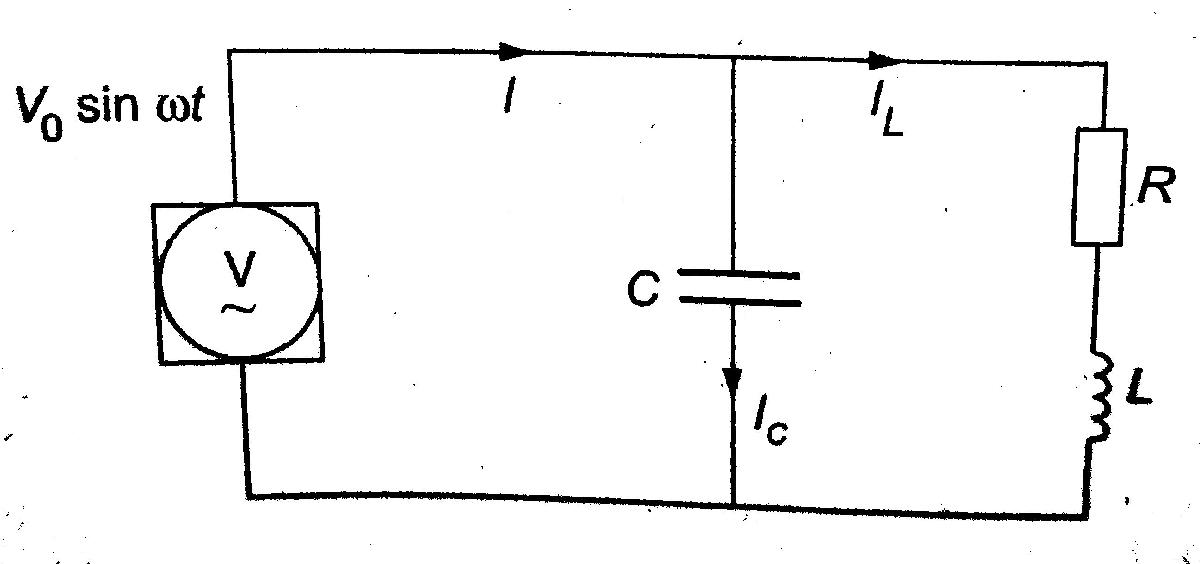

*Резонансная частота*

syms omega01 L C R omega0 Q0
omega01==sqrt(1/(L*C)-R^2/L^2)==omega0*sqrt(1-1/Q0^2)

$$ans = \left(\omega_{01}=\sqrt{\frac{1}{C\,L}-\frac{R^{2}}{L^{2}}}\right)=\omega_{0}\,\sqrt{1-\frac{1}{{Q_{0}}^{2}}}$$

*Импеданс*

syms Z omega R L C
Z==(R+1j*omega*L)/(1-omega^2*L*C+1j*omega*R*C)

$$ans = Z=\frac{R+L\,\omega \,\mathrm{i}}{-C\,L\,\omega^{2}+\mathrm{i}\,C\,R\,\omega +1}$$

В частности, если $\omega =\omega_0^{\prime }$

Z==R*Q0^2==L/(R*C)

$$ans = \left(Z={Q_{0}}^{2}\,R\right)=\frac{L}{C\,R}$$

*Добротность параллельной цепи*

syms Q01
Q01==L/R*omega01==Q0*sqrt(1-1/Q0^2)

$$ans = \left(Q_{01}=\frac{L\,\omega_{01}}{R}\right)=Q_{0}\,\sqrt{1-\frac{1}{{Q_{0}}^{2}}}$$

*Ширина полосы (в Гц)*

B==(omega1-omega2)/(2*pi)==omega0/(2*pi*Q0)

$$ans = \left(B=\frac{\omega_{1}-\omega_{2}}{2\,\pi }\right)=\frac{\omega_{0}}{2\,Q_{0}\,\pi }$$

*Формулы для* omega=omega01

syms I_L I_C I
I_L==-1j*Q0*I, I_C==1j*Q0*I

$$ans = I_{L}=-\text{I}\,Q_{0}\,\mathrm{i}$$

$$ans = I_{C}=\text{I}\,Q_{0}\,\mathrm{i}$$

Приблизительная эквивалентная цепь для Q0

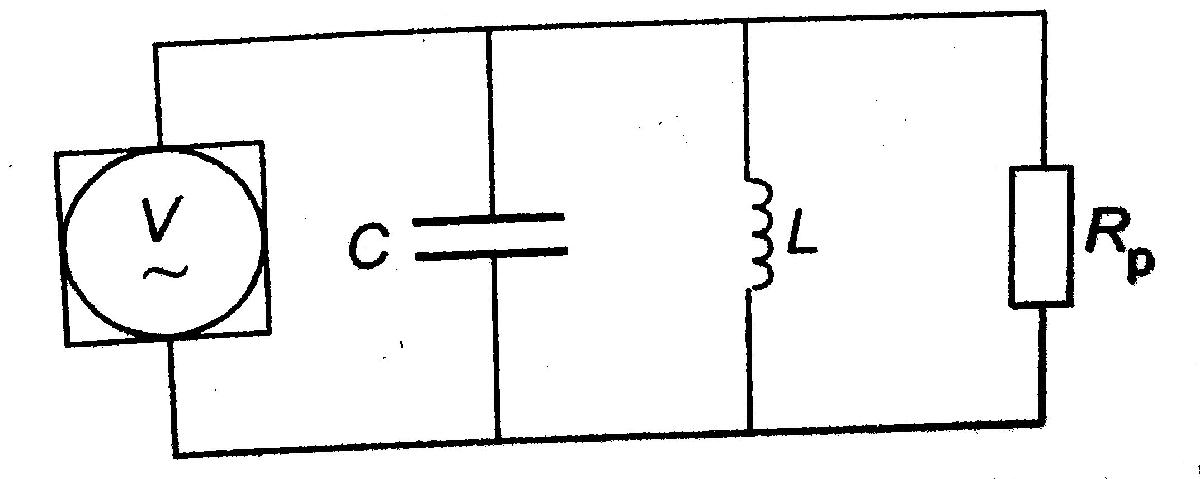 

syms R_p delta
R_p==omega0^2*L^2/R*Q0^2*R

$$ans = R_{p}=L^{2}\,{Q_{0}}^{2}\,{\omega_{0}}^{2}$$

Z==R_p/(1+1j*2*delta*Q0)

$$ans = Z=\frac{R_{p}}{1+2\,Q_{0}\,\delta \,\mathrm{i}}$$

delta==(omega-omega0)/omega0 % - относительная разность частот

$$ans = \delta =\frac{\omega -\omega_{0}}{\omega_{0}}$$